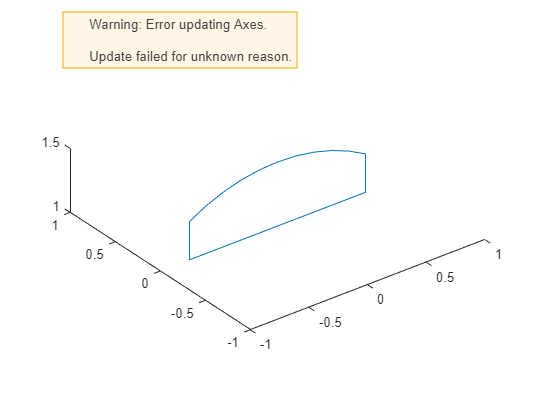

t = linspace(1,2,11)*pi/3; x = 1.5*cos(t); z = 1.5*sin(t);
x = [x,flip(x)]; z = [z, 0*z+1];
x = [x,x(1)]; z = [z,z(1)]; 
y = 0*x;
figure
plot3(x, y, z); daspect([1,1,1]);

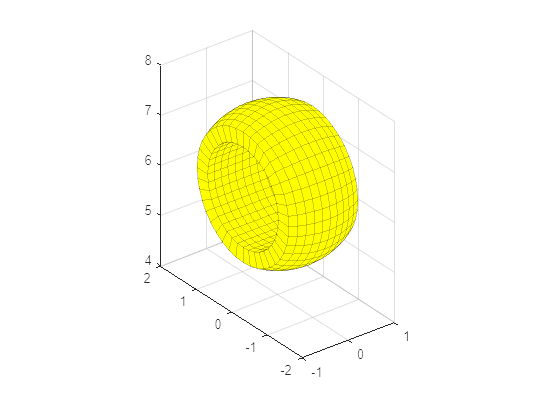


X = x; Y = y; Z = z; xyz = [x; y; z];
M = RotMat([1,0,0],pi/20);
for i = 1:40
    xyz = M*xyz;
    X = [X;xyz(1,:)]; Y = [Y;xyz(2,:)]; Z = [Z;xyz(3,:)];
end
Xs1 = X; Ys1 = Y; Zs1 = Z+6.2;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); daspect([1,1,1]);

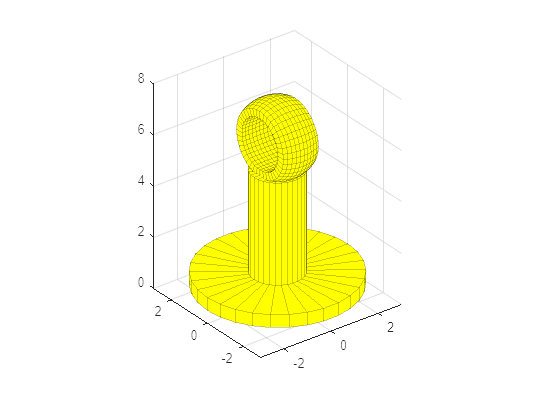


[Xs2, Ys2, Zs2] = cylinder([0,1,1,3,3,0], 30);
Zs2([1,2],:) = 5; Zs2([3,4],:) = 1; Zs2([5,6],:) = 0.5;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); daspect([1,1,1]);
ax = gca;
Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);

## Test Base Rotation about z

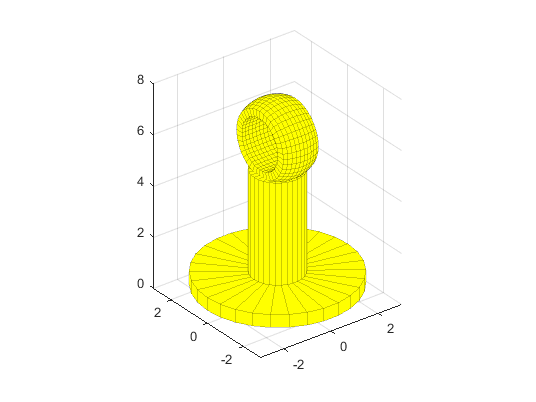


figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); daspect([1,1,1]);
ax = gca;
Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
for b = (0:.02:2)*pi
    % Z-axis rotation matrix
    Rz = makehgtform('zrotate',b);
    % set the transform Matrix property
    set(Base,'Matrix',Rz)
    drawnow
end

BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));

## Make Connecting Cylinder

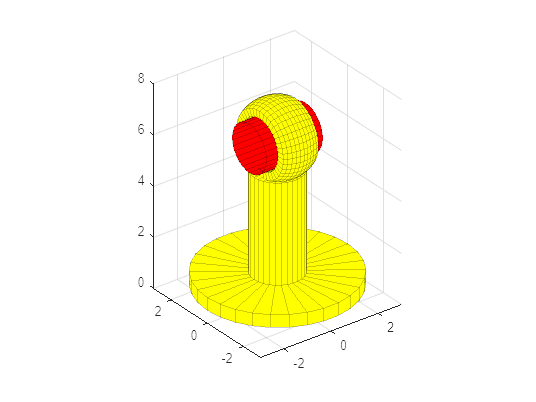


[Z2, Y2, X2] = cylinder(0.95, 30); X2 = X2*2.4-1.2;
Zs3 = Z2; Xs3 = X2;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');daspect([1,1,1]);
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 

## Test Swing of Arm1

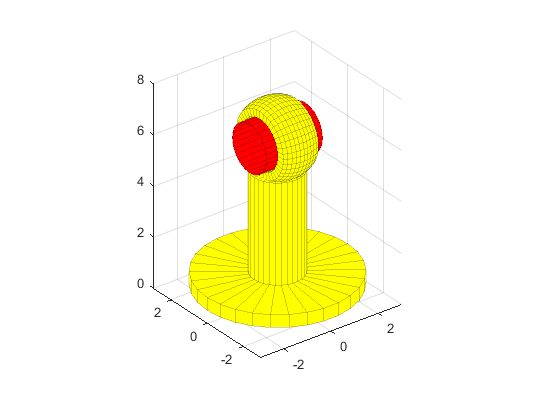


figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');daspect([1,1,1]);
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
for r = (-0.7:.02:0.7)*pi
    % x-axis rotation matrix
    Rx = makehgtform('xrotate',r);
    % set the transform Matrix property
    set(Arm1,'Matrix',Rx)
    drawnow
end

Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));

## Add Joint Head

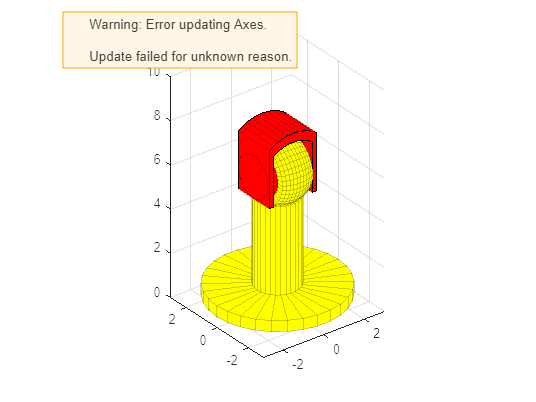


t = linspace(0.9,2.1,11)*pi/3;
x = [1.6*cos(t(1)), 1.6*cos(t), 1.6*cos(t(end)), ....
    2.0*cos(t(end)), 2.0*cos(flip(t)), 2.0*cos(t(1)), 1.6*cos(t(1))];
z = [-1, 1.6*sin(t), -1, -1, 2.0*sin(flip(t)), -1, -1];
y = 0*x;
X3 = [x;x]; Y3 = [y+1; y-1]; Z3 = [z;z];
Xs4 = X3; Ys4 = Y3; Zs4 = Z3;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
daspect([1,1,1]);

## Test Coupled Rotation

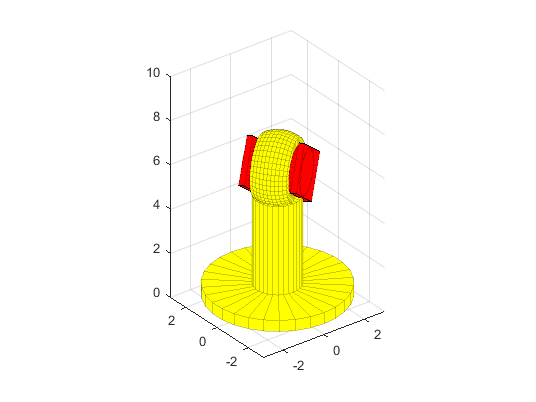


t = linspace(0.9,2.1,11)*pi/3;
x = [1.6*cos(t(1)), 1.6*cos(t), 1.6*cos(t(end)), ....
    2.0*cos(t(end)), 2.0*cos(flip(t)), 2.0*cos(t(1)), 1.6*cos(t(1))];
z = [-1, 1.6*sin(t), -1, -1, 2.0*sin(flip(t)), -1, -1];
y = 0*x;
X3 = [x;x]; Y3 = [y+1; y-1]; Z3 = [z;z];
Xs4 = X3; Ys4 = Y3; Zs4 = Z3;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
daspect([1,1,1]); axis([-3,3,-3,3,0,10])
for r = (-0.7:.01:0.7)*pi
    Arm1Swing(r);
    BaseRotate(r);
    drawnow
end

## section

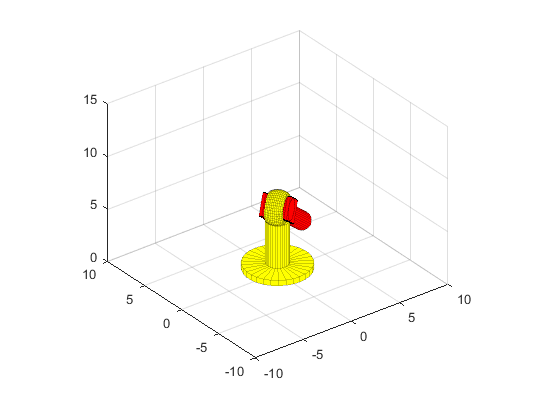


[Xs5, Ys5, Zs5] = cylinder([0,0.8,0.8,0], 30);
Zs5([1,2],:) = 8.8; Zs5([3,4],:) = 1.8;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); set(S5,'Parent',Arm1); 
daspect([1,1,1]); axis([-10,10,-10,10,0,15])
for r = (-0.7:.01:0.7)*pi
    Arm1Swing(r);
    BaseRotate(r);
    drawnow
end

## Add Hinge1 

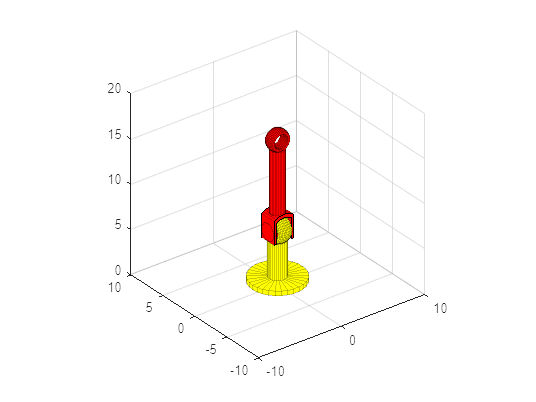

Xs6 = 0.8*Y; Ys6 = 0.8*X; Zs6 = 0.8*Z;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); set(S5,'Parent',Arm1); 
Offset2 = hgtransform('Parent',Arm1); 
Mz = makehgtform('translate',[0, 0, 9.8]); set(Offset2,'Matrix',Mz);
Hinge1 = hgtransform('Parent',Offset2);
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r');  set(S6,'Parent',Hinge1); 
daspect([1,1,1]); axis([-10,10,-10,10,0,20])

## Add Connecting Rod

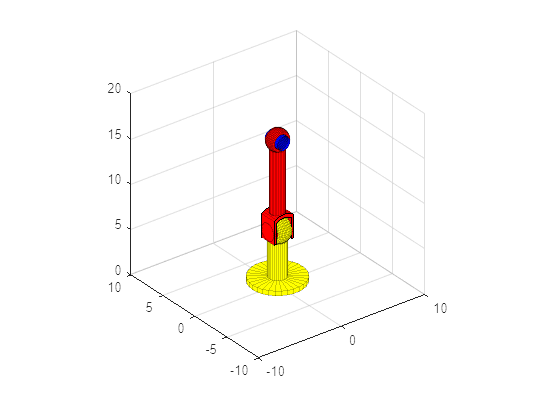

Xs7 = 0.8*Y2; Ys7 = 0.8*X2; Zs7 = 0.8*Z2;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); set(S5,'Parent',Arm1); 
Offset2 = hgtransform('Parent',Arm1); 
Mz = makehgtform('translate',[0, 0, 9.8]); set(Offset2,'Matrix',Mz);
Hinge1 = hgtransform('Parent',Offset2);
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r');  set(S6,'Parent',Hinge1);
Arm2 = hgtransform('Parent',Hinge1);
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); set(S7,'Parent',Arm2); 
daspect([1,1,1]); axis([-10,10,-10,10,0,20]);

## Add Joint Cap

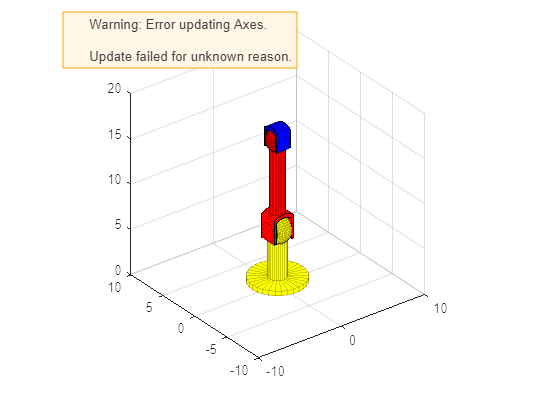

Xs8 = 0.8*Y3; Ys8 = 0.8*X3; Zs8 = 0.8*Z3;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); set(S5,'Parent',Arm1); 
Offset2 = hgtransform('Parent',Arm1); 
Mz = makehgtform('translate',[0, 0, 9.8]); set(Offset2,'Matrix',Mz);
Hinge1 = hgtransform('Parent',Offset2);
Hinge1Rotate = @(theta) set(Hinge1,'Matrix', makehgtform('zrotate',theta));
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r');  set(S6,'Parent',Hinge1);
Arm2 = hgtransform('Parent',Hinge1);
Arm2Swing = @(theta) set(Arm2,'Matrix', makehgtform('yrotate',theta));
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); set(S7,'Parent',Arm2); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b'); set(S8 ,'Parent',Arm2); 
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); set(S8a,'Parent',Arm2); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); set(S8b,'Parent',Arm2); 
daspect([1,1,1]); axis([-10,10,-10,10,0,20]);

## Test Arm2

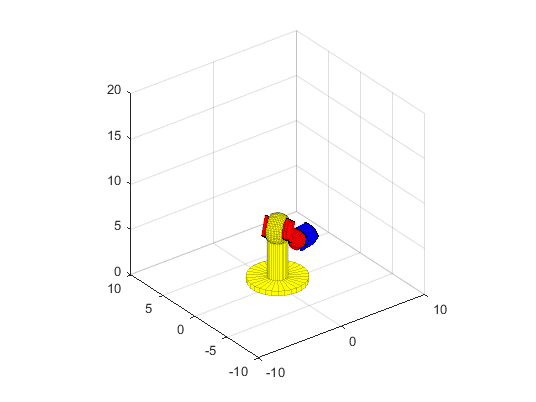

figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); set(S5,'Parent',Arm1); 
Offset2 = hgtransform('Parent',Arm1); 
Mz = makehgtform('translate',[0, 0, 9.8]); set(Offset2,'Matrix',Mz);
Hinge1 = hgtransform('Parent',Offset2);
Hinge1Rotate = @(theta) set(Hinge1,'Matrix', makehgtform('zrotate',theta));
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r');  set(S6,'Parent',Hinge1);
Arm2 = hgtransform('Parent',Hinge1);
Arm2Swing = @(theta) set(Arm2,'Matrix', makehgtform('yrotate',theta));
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); set(S7,'Parent',Arm2); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b'); set(S8 ,'Parent',Arm2); 
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); set(S8a,'Parent',Arm2); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); set(S8b,'Parent',Arm2); 
daspect([1,1,1]); axis([-10,10,-10,10,0,20]);
for r = (-0.7:.01:0.7)*pi
    Arm1Swing(r);
    BaseRotate(r);
    Hinge1Rotate(r);
    Arm2Swing(r);
    drawnow
end

## Complete Arms2

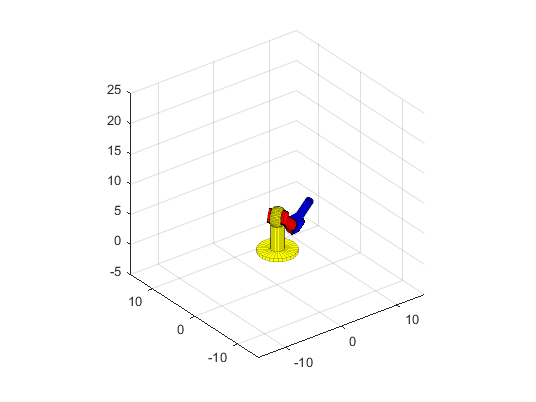

[Xs9, Ys9, Zs9] = cylinder([0,0.6,0.6,0], 30);
Zs9([1,2],:) = 5.5; Zs9([3,4],:) = 1.5; 
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); set(S5,'Parent',Arm1); 
Offset2 = hgtransform('Parent',Arm1); 
Mz = makehgtform('translate',[0, 0, 9.8]); set(Offset2,'Matrix',Mz);
Hinge1 = hgtransform('Parent',Offset2);
Hinge1Rotate = @(theta) set(Hinge1,'Matrix', makehgtform('zrotate',theta));
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r');  set(S6,'Parent',Hinge1);
Arm2 = hgtransform('Parent',Hinge1);
Arm2Swing = @(theta) set(Arm2,'Matrix', makehgtform('yrotate',theta));
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); set(S7,'Parent',Arm2); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b'); set(S8 ,'Parent',Arm2); 
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); set(S8a,'Parent',Arm2); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); set(S8b,'Parent',Arm2); 
S9 = surf(Xs9, Ys9, Zs9, EdgeAlpha=0.2, FaceColor='b'); set(S9,'Parent',Arm2); 
daspect([1,1,1]); axis([-15,15,-15,15,-5,25]);
for r = (-0.7:.01:0.7)*pi
    Arm1Swing(r);
    BaseRotate(r);
    Hinge1Rotate(r);
    Arm2Swing(r);
    drawnow
end

## Add GripperBase to the Assembly

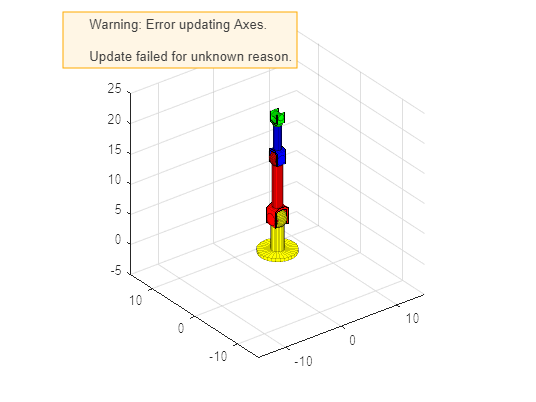

[Xs10, Ys10, Zs10] = cylinder(0.7, 30); Zs10 = 0.5*Zs10-1.5;
Xs11 = 0.7*Y3; Ys11 = 0.7*X3; Zs11 = -0.6*Z3;
[Z12, X12, Y12] = cylinder(0.5, 30); 
Ys12 = Y12*1.8-0.9; Xs12 = X12; Zs12 = Z12;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); set(S5,'Parent',Arm1); 
Offset2 = hgtransform('Parent',Arm1); 
Mz = makehgtform('translate',[0, 0, 9.8]); set(Offset2,'Matrix',Mz);
Hinge1 = hgtransform('Parent',Offset2);
Hinge1Rotate = @(theta) set(Hinge1,'Matrix', makehgtform('zrotate',theta));
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r');  set(S6,'Parent',Hinge1);
Arm2 = hgtransform('Parent',Hinge1);
Arm2Swing = @(theta) set(Arm2,'Matrix', makehgtform('yrotate',theta));
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); set(S7,'Parent',Arm2); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b'); set(S8 ,'Parent',Arm2); 
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); set(S8a,'Parent',Arm2); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); set(S8b,'Parent',Arm2); 
S9 = surf(Xs9, Ys9, Zs9, EdgeAlpha=0.2, FaceColor='b'); set(S9,'Parent',Arm2); 
Offset3 = hgtransform('Parent',Arm2); 
Mz = makehgtform('translate',[0, 0, 7]); set(Offset3,'Matrix',Mz);
GripperBase = hgtransform('Parent',Offset3);
S10 = surf(Xs10, Ys10, Zs10, EdgeAlpha=0.2, FaceColor='g'); set(S10,'Parent',GripperBase); 
S11 = surf(Xs11, Ys11, Zs11, EdgeAlpha=0.2, FaceColor='g'); set(S11,'Parent',GripperBase); 
S11a = patch(Xs11(1,:), Ys11(1,:), Zs11(1,:), 'g'); set(S11a,'Parent',GripperBase); 
S11b = patch(Xs11(2,:), Ys11(2,:), Zs11(2,:), 'g'); set(S11b,'Parent',GripperBase); 
S12 = surf(Xs12, Ys12, Zs12, EdgeAlpha=0.2, FaceColor='g'); set(S12,'Parent',GripperBase); 
GripperBaseTurn = @(theta) set(GripperBase,'Matrix', makehgtform('zrotate',theta));
daspect([1,1,1]); axis([-15,15,-15,15,-5,25]);

## Test All Rotations

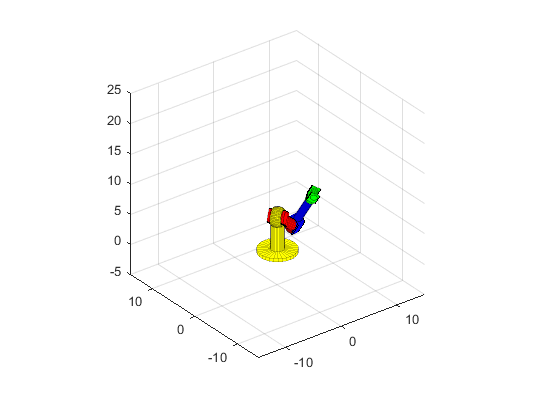

figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); set(S5,'Parent',Arm1); 
Offset2 = hgtransform('Parent',Arm1); 
Mz = makehgtform('translate',[0, 0, 9.8]); set(Offset2,'Matrix',Mz);
Hinge1 = hgtransform('Parent',Offset2);
Hinge1Rotate = @(theta) set(Hinge1,'Matrix', makehgtform('zrotate',theta));
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r');  set(S6,'Parent',Hinge1);
Arm2 = hgtransform('Parent',Hinge1);
Arm2Swing = @(theta) set(Arm2,'Matrix', makehgtform('yrotate',theta));
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); set(S7,'Parent',Arm2); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b'); set(S8 ,'Parent',Arm2); 
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); set(S8a,'Parent',Arm2); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); set(S8b,'Parent',Arm2); 
S9 = surf(Xs9, Ys9, Zs9, EdgeAlpha=0.2, FaceColor='b'); set(S9,'Parent',Arm2); 
Offset3 = hgtransform('Parent',Arm2); 
Mz = makehgtform('translate',[0, 0, 7]); set(Offset3,'Matrix',Mz);
GripperBase = hgtransform('Parent',Offset3);
S10 = surf(Xs10, Ys10, Zs10, EdgeAlpha=0.2, FaceColor='g'); set(S10,'Parent',GripperBase); 
S11 = surf(Xs11, Ys11, Zs11, EdgeAlpha=0.2, FaceColor='g'); set(S11,'Parent',GripperBase); 
S11a = patch(Xs11(1,:), Ys11(1,:), Zs11(1,:), 'g'); set(S11a,'Parent',GripperBase); 
S11b = patch(Xs11(2,:), Ys11(2,:), Zs11(2,:), 'g'); set(S11b,'Parent',GripperBase); 
GripperBaseTurn = @(theta) set(GripperBase,'Matrix', makehgtform('zrotate',theta));
S12 = surf(Xs12, Ys12, Zs12, EdgeAlpha=0.2, FaceColor='g'); set(S12,'Parent',GripperBase);
daspect([1,1,1]); axis([-15,15,-15,15,-5,25]);
for r = (-0.7:.01:0.7)*pi
    Arm1Swing(r);
    BaseRotate(r);
    Hinge1Rotate(r);
    Arm2Swing(r);
    GripperBaseTurn(r)
    drawnow
end

## Gripper Design

t = linspace(0, 2, 201)*pi;
figure
x = 0.5*cos(t); z = 0.5*sin(t); y = 0*x;
plot3(x, y, z); daspect([1,1,1]); hold on;
x = 0.1*cos(t); z = 0.1*sin(t); y = 0*x;
plot3(x, y, z+2); 
v = fsolve(@(v)[v'*v-6.25; (v-[0;-2])'*(v-[0;-2])-4.41], [1;1]); v(2) = -v(2);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


u = fsolve(@(u)[u'*u-12.25; (u-[0;-2])'*(u-[0;-2])-15.21], [1;1]); u(2) = -u(2);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


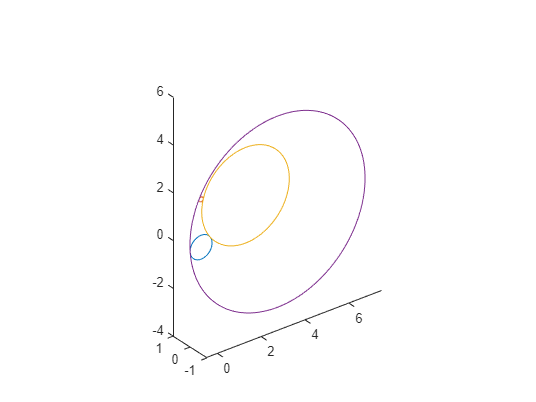

plot3(2*cos(t)+v(1), y, 2*sin(t)+v(2)); 
plot3(4*cos(t)+u(1), y, 4*sin(t)+u(2)); 

## Circular Tangency

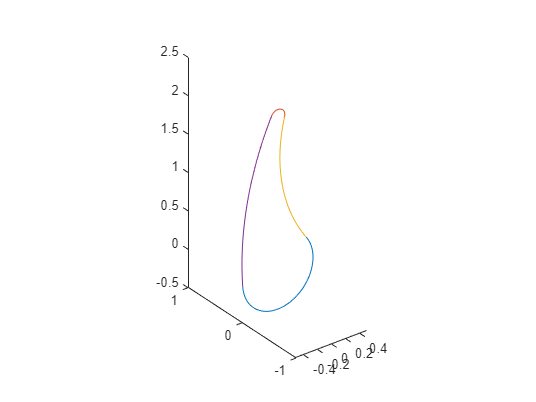

figure
t1a = dir([0;0], v);  t1b = dir([0;0], u);
t1 = linspace(t1b-pi, t1a, 50);
plot3(0.5*cos(t1), 0*t1, 0.5*sin(t1)); hold on; daspect([1,1,1]);

t2a = dir([0;2], v);  t2b = dir([0;2], u);
t2 = linspace(t2b, pi+t2a, 10);
plot3(0.1*cos(t2), 0*t2, 0.1*sin(t2)+2); 

t3a = dir(v,[0;0]);  t3b = dir(v, [0;2]);
t3 = linspace(t3b, 2*pi+t3a, 50);
plot3(2*cos(t3)+v(1), 0*t3, 2*sin(t3)+v(2)); 

t4a = dir(u,[0;0]);  t4b = dir(u, [0;2]);
t4 = linspace(t4b, 2*pi+t4a, 50);
plot3(4*cos(t4)+u(1), 0*t4, 4*sin(t4)+u(2)); 

## Gripper Completed

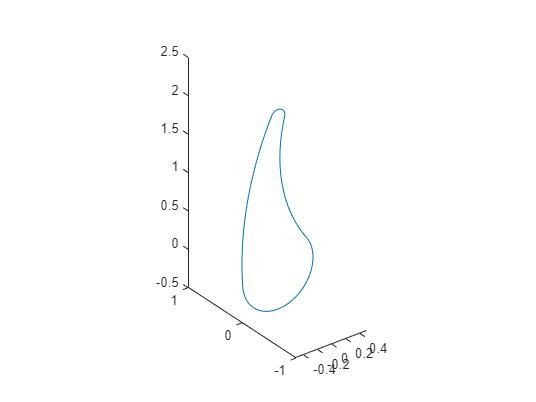

figure
x = [0.5*cos(t1), 2*cos(flip(t3))+v(1), 0.1*cos(t2), 4*cos(t4)+u(1)];
z = [0.5*sin(t1), 2*sin(flip(t3))+v(2), 0.1*sin(t2)+2, 4*sin(t4)+u(2)];
y = 0*x;
plot3(x, y, z);   daspect([1,1,1]);

## Add Gripper to the Assembly

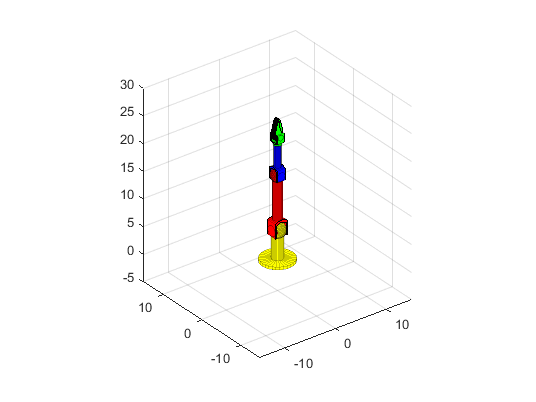

Xs13 = 1.5*[x;x]; Ys13 = [y-0.1;y+0.1]; Zs13 = 1.5*[z;z];
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); set(S5,'Parent',Arm1); 
Offset2 = hgtransform('Parent',Arm1); 
Mz = makehgtform('translate',[0, 0, 9.8]); set(Offset2,'Matrix',Mz);
Hinge1 = hgtransform('Parent',Offset2);
Hinge1Rotate = @(theta) set(Hinge1,'Matrix', makehgtform('zrotate',theta));
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r');  set(S6,'Parent',Hinge1);
Arm2 = hgtransform('Parent',Hinge1);
Arm2Swing = @(theta) set(Arm2,'Matrix', makehgtform('yrotate',theta));
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); set(S7,'Parent',Arm2); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b'); set(S8 ,'Parent',Arm2); 
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); set(S8a,'Parent',Arm2); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); set(S8b,'Parent',Arm2); 
S9 = surf(Xs9, Ys9, Zs9, EdgeAlpha=0.2, FaceColor='b'); set(S9,'Parent',Arm2); 
Offset3 = hgtransform('Parent',Arm2); 
Mz = makehgtform('translate',[0, 0, 7]); set(Offset3,'Matrix',Mz);
GripperBase = hgtransform('Parent',Offset3);
S10 = surf(Xs10, Ys10, Zs10, EdgeAlpha=0.2, FaceColor='g'); set(S10,'Parent',GripperBase); 
S11 = surf(Xs11, Ys11, Zs11, EdgeAlpha=0.2, FaceColor='g'); set(S11,'Parent',GripperBase); 
S11a = patch(Xs11(1,:), Ys11(1,:), Zs11(1,:), 'g'); set(S11a,'Parent',GripperBase); 
S11b = patch(Xs11(2,:), Ys11(2,:), Zs11(2,:), 'g'); set(S11b,'Parent',GripperBase); 
GripperBaseTurn = @(theta) set(GripperBase,'Matrix', makehgtform('zrotate',theta));
S12 = surf(Xs12, Ys12, Zs12, EdgeAlpha=0.2, FaceColor='g'); set(S12,'Parent',GripperBase);
GripperLeft = hgtransform('Parent',GripperBase);
for d = [-1:1]*0.4
    S13 = surf(Xs13, Ys13+d, Zs13, EdgeAlpha=0.2, FaceColor='g'); set(S13,'Parent',GripperLeft); 
    S13a = patch(Xs13(1,:), Ys13(1,:)+d, Zs13(1,:), 'g'); set(S13a,'Parent',GripperLeft); 
    S13b = patch(Xs13(2,:), Ys13(2,:)+d, Zs13(2,:), 'g'); set(S13b,'Parent',GripperLeft); 
end
GripperRight = hgtransform('Parent',GripperBase);
for d = [-1,1]*0.2
    S13 = surf(-Xs13, Ys13+d, Zs13, EdgeAlpha=0.2, FaceColor='g'); set(S13,'Parent',GripperRight); 
    S13a = patch(-Xs13(1,:), Ys13(1,:)+d, Zs13(1,:), 'g'); set(S13a,'Parent',GripperRight); 
    S13b = patch(-Xs13(2,:), Ys13(2,:)+d, Zs13(2,:), 'g'); set(S13b,'Parent',GripperRight); 
end
daspect([1,1,1]); axis([-15,15,-15,15,-5,30]);
for i = 1:10
    GripOpen(GripperLeft, GripperRight);
    GripClose(GripperLeft, GripperRight);
end

## Test Gripping

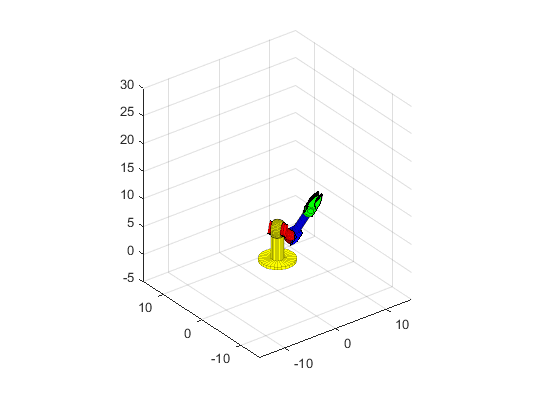

figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
ax = gca; Base = hgtransform('Parent',ax); 
set(S2,'Parent',Base); set(S1,'Parent',Base);
BaseRotate = @(theta) set(Base,'Matrix', makehgtform('zrotate',theta));
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
Offset1 = hgtransform('Parent',Base); 
Mz = makehgtform('translate',[0, 0, 6.2]);  set(Offset1,'Matrix',Mz);
Arm1 = hgtransform('Parent',Offset1); set(S3,'Parent',Arm1); 
Arm1Swing = @(theta) set(Arm1,'Matrix', makehgtform('xrotate',theta));
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r'); set(S4,'Parent',Arm1); 
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r');  set(S4a,'Parent',Arm1); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); set(S4b,'Parent',Arm1); 
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); set(S5,'Parent',Arm1); 
Offset2 = hgtransform('Parent',Arm1); 
Mz = makehgtform('translate',[0, 0, 9.8]); set(Offset2,'Matrix',Mz);
Hinge1 = hgtransform('Parent',Offset2);
Hinge1Rotate = @(theta) set(Hinge1,'Matrix', makehgtform('zrotate',theta));
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r');  set(S6,'Parent',Hinge1);
Arm2 = hgtransform('Parent',Hinge1);
Arm2Swing = @(theta) set(Arm2,'Matrix', makehgtform('yrotate',theta));
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); set(S7,'Parent',Arm2); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b'); set(S8 ,'Parent',Arm2); 
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); set(S8a,'Parent',Arm2); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); set(S8b,'Parent',Arm2); 
S9 = surf(Xs9, Ys9, Zs9, EdgeAlpha=0.2, FaceColor='b'); set(S9,'Parent',Arm2); 
Offset3 = hgtransform('Parent',Arm2); 
Mz = makehgtform('translate',[0, 0, 7]); set(Offset3,'Matrix',Mz);
GripperBase = hgtransform('Parent',Offset3);
S10 = surf(Xs10, Ys10, Zs10, EdgeAlpha=0.2, FaceColor='g'); set(S10,'Parent',GripperBase); 
S11 = surf(Xs11, Ys11, Zs11, EdgeAlpha=0.2, FaceColor='g'); set(S11,'Parent',GripperBase); 
S11a = patch(Xs11(1,:), Ys11(1,:), Zs11(1,:), 'g'); set(S11a,'Parent',GripperBase); 
S11b = patch(Xs11(2,:), Ys11(2,:), Zs11(2,:), 'g'); set(S11b,'Parent',GripperBase); 
GripperBaseTurn = @(theta) set(GripperBase,'Matrix', makehgtform('zrotate',theta));
S12 = surf(Xs12, Ys12, Zs12, EdgeAlpha=0.2, FaceColor='g'); set(S12,'Parent',GripperBase);
GripperLeft = hgtransform('Parent',GripperBase);
for d = [-1:1]*0.4
    S13 = surf(Xs13, Ys13+d, Zs13, EdgeAlpha=0.2, FaceColor='g'); set(S13,'Parent',GripperLeft); 
    S13a = patch(Xs13(1,:), Ys13(1,:)+d, Zs13(1,:), 'g'); set(S13a,'Parent',GripperLeft); 
    S13b = patch(Xs13(2,:), Ys13(2,:)+d, Zs13(2,:), 'g'); set(S13b,'Parent',GripperLeft); 
end
GripperRight = hgtransform('Parent',GripperBase);
for d = [-1,1]*0.2
    S13 = surf(-Xs13, Ys13+d, Zs13, EdgeAlpha=0.2, FaceColor='g'); set(S13,'Parent',GripperRight); 
    S13a = patch(-Xs13(1,:), Ys13(1,:)+d, Zs13(1,:), 'g'); set(S13a,'Parent',GripperRight); 
    S13b = patch(-Xs13(2,:), Ys13(2,:)+d, Zs13(2,:), 'g'); set(S13b,'Parent',GripperRight); 
end
daspect([1,1,1]); axis([-15,15,-15,15,-5,30]); i = 1;
for r = (-0.7:.01:0.7)*pi
    Arm1Swing(r);
    BaseRotate(r);
    Hinge1Rotate(r);
    Arm2Swing(r);
    GripperBaseTurn(r)
    GripOpen(GripperLeft, GripperRight, i);
    GripClose(GripperLeft, GripperRight, i);
    i = i + 1;
    drawnow
end

function M = RotMat(U,theta)
c = cos(theta); s = sin(theta); ux = U(1); uy = U(2); uz = U(3);
M = [ux*ux*(1 - c) +    c  uy*ux*(1 - c) - uz*s  uz*ux*(1 - c) + uy*s
     uy*ux*(1 - c) + uz*s  uy*uy*(1 - c) +    c  uz*uy*(1 - c) - ux*s
     uz*ux*(1 - c) - uy*s  uy*uz*(1 - c) + ux*s  uz*uz*(1 - c) +    c]; 
end

function v = dir(pt1, pt2)
    u = pt2-pt1;
    v = atan2(u(2), u(1));
end

function GripOpen(GripLeft, GripRight, n)
    if nargin < 3
        for r = 0:0.1:1
            set(GripLeft,'Matrix', makehgtform('yrotate',-r));
            set(GripRight,'Matrix', makehgtform('yrotate',r));
            drawnow
        end
    else
        n = mod(n-1, 20)+1;
        if(n <= 10)
            r = n*0.1;
            set(GripLeft,'Matrix', makehgtform('yrotate',-r));
            set(GripRight,'Matrix', makehgtform('yrotate',r));
            drawnow
        end
    end
end

function GripClose(GripLeft, GripRight, n)
    if nargin < 3
        for r = 1:-0.1:0
            set(GripLeft,'Matrix', makehgtform('yrotate',-r));
            set(GripRight,'Matrix', makehgtform('yrotate',r));
            drawnow
        end
    else
        n = mod(n-1, 20)+1;
        if(n > 10)
            r = (20-n)*0.1;
            set(GripLeft,'Matrix', makehgtform('yrotate',-r));
            set(GripRight,'Matrix', makehgtform('yrotate',r));
            drawnow
        end
    end
end